# **THIS IS 12.3 **

**Trefethen's Exploration of Random Matrices**

The aim of this exercise is to explore some properties of random

matrices A = randn(m)/sqrt(m) (the normalization makes the limiting

behavior clean, as $m \rightarrow \infty$

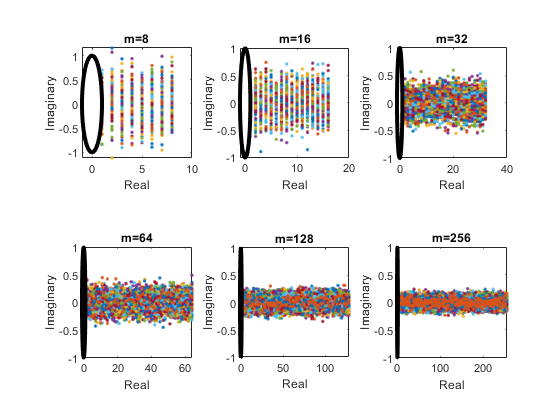

clear; close all;
ratio = zeros(100,9);
th=linspace(-pi,pi,200);
hold on;
kmax=8;
ks=3:kmax;
Es=zeros(2^kmax,kmax);
for k = 3:kmax
    m=2^k;
    subplot(2,3,k-2)
    for j=1:100
        if j == 1
            hold off;
        else
            hold on;
        end
        A = randn(m)/sqrt(m);
        B=triu(A);
        E=eig(B);
        Es(1:m,k)=abs(E);
        plot(E,'.');
        rho=max(abs(E));
        n2=norm(B,2);
        ratio(j,k)=n2/rho;
    end
    plot(cos(th),sin(th), 'k','linewidth',3)
    xlabel('Real')
    ylabel('Imaginary')
    title(['m=',num2str(m)]);
    axis square
    hold off
end

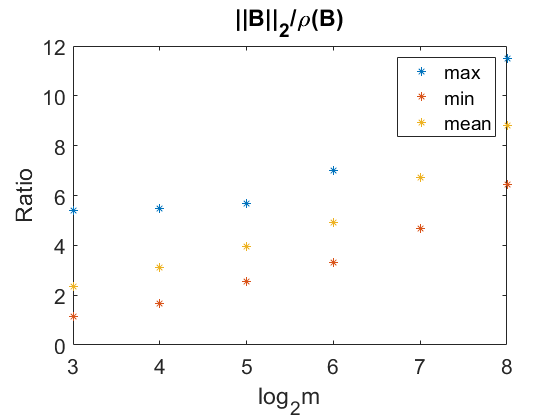

%print('-dpdf','HW12_3');
%hold off;
figure(2)
plot(ks,max(ratio(:,ks)),'<',ks,min(ratio(:,ks)),'o',ks,mean(ratio(:,ks)),'v','Marker','*')
set (gca,'fontsize',16);
legend('max','min','mean');
title('||B||_2/\rho(B)');
xlabel('log_2m');
ylabel('Ratio')

%print('-dpdf','HW12_3_2')
figure(3)
hold

Current plot held


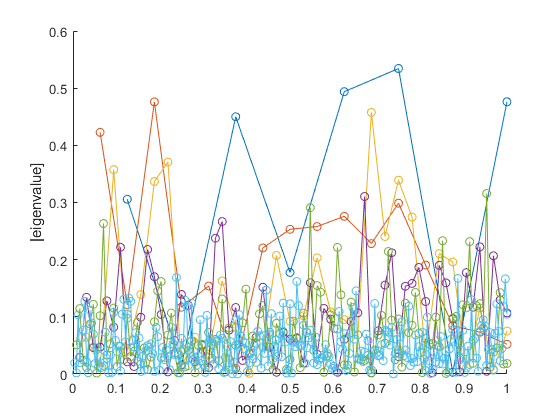

for k=3:kmax
    vv=(1:2^k)./2^k;
    plot(vv,Es(1:2^k,k),'-o')
end
ylabel('|eigenvalue]')
xlabel('normalized index')

**Questions:**

**star questions are optional**

*(1) What does the code compute?*

*(2) What does the  spectrum look like as m gets large?*

*(3) How does the spectral radius rho(A) behave as m gets large?*

*(4) Does rho(A) <=||A|| hold, particularly as m gets large?*

*(5*) What portion of real mXm random matrices seem to have *

*smallest singular values sigma_min <= 1/2, 1/4, 1/8....?*

*(for this you will need to write some code)*

*(6*) How do all of the questions get answered if the matrix is random triangular rather than full? *

*(7*) modify the matrix to be A=rand(m)/sqrt(m), uniform random distribution. What happens?*